## 조건 파일 Struct 불러오기

mcad=actxserver('motorcad.appautomation');

## 조건 struct

For case Num

   caseNum별 파일이름, 경로 할당

for CaseInPort = 1:1:(numCases/numPorts)
    caseNum = (spmdIndex-1)*(numCases/numPorts)+CaseInPort;
    parts = strsplit(refMotFilePath, filesep);
    parentPath = fullfile(parts{1:end-2});
    [filepath,name,ext] = fileparts(refMotFilePath);
    newFolder = fullfile(parentPath, 'DOE', [name, '_Design', sprintf('%03d', caseNum)]);
    parts = strsplit(newFolder, filesep);
    newMotFilePath = fullfile(newFolder, strcat(parts{end}, '.mot'));

   불러오기

    activeServers(spmdIndex).LoadFromFile(refMotFilePath);  % ref 파일 땡겨오기


   Build Check

    [Success, isBuildSucceeded]=activeServers(spmdIndex).GetModelBuilt_Lab();  % 모델 빌드 여부 체크

  조건 파일 Struct setting

    LabCalc12p.DCBusVoltage=600;
    LabCalc12p.ModulationIndex_MotorLAB=1;
    OperatingMode_Lab           = 0
    ControlStrat_MotorLAB       = 0
    DCCurrentLimit_Lab          = 0  
       
    LabCalc12p.StatorIronLossBuildFactor    =1
    LabCalc12p.RotorIronLossBuildFactor     =1.5
    MagnetLossBuildFactor

    setMcadVariable(LabCalc12p,mcad)




## 0)Weight Calc 가져오기

According to *Ingineerix*, the Plaid version of the motor weighs about 99 lbs (45 kg), while the rest of the drive unit (single-speed transmission and inverter) weighs about 110 lbs (50 kg), which gives us a relatively low total of roughly 220 lbs (95 kg).

"This is a look inside the actual PMSRM motor of the Plaid drive unit. This is essentially the "Raven" drive unit which itself is a repackaged Model 3 PMSRM rear motor. The main change for Plaid was upgrading the rotor for higher speed operation by incorporating a carbon-fiber overwrap to keep the rotor from coming apart at 200 MPH/320 KPH.

The Motor itself with stator/field, rotor and housing only weighs 99 LBS/45 KG. The rest of the drive unit adds about 110 LBS/50 KG for a total of about 210 LBS/95 KG."

The Model S Plaid is the first and

% weight variable
mcad.DoWeightCalculation()                                              % Weight calculation
[ex, o_Weight_Mag       ]= mcad.GetVariable("Weight_Calc_Magnet")       % Magnet's mass 
[ex, o_Weight_Wdg       ]= mcad.GetVariable("Weight_Calc_Copper_Total") % Winding's mass 
[ex, o_Weight_Stat_Core ]= mcad.GetVariable("Weight_Calc_Stator_Lam")   % Stator core's mass  
[ex, o_Weight_Rot_Core  ]= mcad.GetVariable("Weight_Calc_Rotor_Lam")    % Rotor core's mass
[ex, Weight_Shaft       ]= mcad.GetVariable("Weight_Shaft_Active")      % Shaft's mass  
[ex, Weight_Act         ]= mcad.GetVariable("Weight_Calc_Total")        % Active mass
[o_Weight_Act           ]= Weight_Act - Weight_Shaft                    % Shaft's mass retrieved

%% 45 kg motor, rest of drvie unit 50kg
o_Weight_Mag+o_Weight_Wdg+o_Weight_Stat_Core+o_Weight_Rot_Core

## 0.1)[LSC] 역기전력 계산

BEMFfund=getFundamentalBEMF(variable,mcad); % From Flux Linkage Map 

## 1)[KSG]DutyCycle

## 2)TN 계산 및 OP계산

- 입력

                �전압 입력, MI,

                제어방식(MTPA-FW, Maximum Efficiency)

             온도

%% McadLABCalcPackage 
    variable.DCBusVoltage                                        =[];              
    variable.ModulationIndex_MotorLAB                            =[]; 
    % operating Mode
    variable.OperatingMode_Lab                       =    []     
    variable.ControlStrat_MotorLAB                   =    []     
    
    % Temperature                                   
    % Stator Winding              
    % variable.Twdg_MotorLAB                        =[];           %ThermalParameters_MotorLAB
    
    variable.TwindingCalc_MotorLAB                   =[];          %ModelParameters_MotorLAB
    
    % AC loss Temperature Scaling                            
    % variable.WindingTemp_ACLoss_Ref_Lab              =[];          %ThermalParameters_MotorLAB
    variable.StatorCopperFreqCompTempExponent        =[];                              
    % Magnet Temperature                                 
    % variable.
    % variable.Tmag_MotorLAB                           =[];         %ThermalParameters_MotorLAB
    variable.TmagnetCalc_MotorLAB                    =[];         %ModelParameters_MotorLAB      
    % Mechanical Loss Temperatures                                  
    % variable.Airgap_Temperature                      =[];          % Magnetics 
    % variable.Bearing_Temperature_F                   =[];          % Magnetics      
    % variable.Bearing_Temperature_R                   =[];
    

            최대전류 입력 (DOE)

        %% Electromagnetic 
    variable.EmagneticCalcType_Lab                     =1;        
    % variable.PowerLim_MotorLAB                         =[];                         %     % If EmagneticCalcType_Lab =1
    % variable.PowerLimVal_MotorLAB                      =[];                         %      % if PowerLim_MotorLAB=1
    variable.SpeedMax_MotorLAB                         =20000;    
    variable.Speedinc_MotorLAB                         =500;    
    variable.SpeedMin_MotorLAB                         =0;

    variable.Imax_MotorLAB                             =DoETable.Imax_MotorLAB(1); 
    % variable.Imax_RMS_MotorLAB                         =[];    
    variable.Iinc_MotorLAB                             =20; 
    variable.Imin_MotorLAB                             =0; 
    % variable.Imin_RMS_MotorLAB                         =[]; 

    출력간격 (전류간격, 속도)

Peak_Power_Array
Peak_Torque_Array

%% 

% mcad.CalculateMagnetic_Lab()                                 % Run calculation


#### Load Elecdata

%%[TB] calc MagLab with Setting Variable
mcad=actxserver('motorcad.appautomation');
mcad.CalculateMagnetic_Lab();
% [TB]
MatFileData=getMatDataCalcMagLab()
% Temporary
% mot_file_dir='Z:\01_Codes_Projects\git_fork_emach\SkkuEMLabProject\LabProj2023v0\DOE\12p72s_VV_Design010\12p72s_VV_Design010'
mot_file_dir='Z:\01_Codes_Projects\git_fork_emach\SkkuEMLabProject\LabProj2023v1\8p48s_Delta_SAPark\MCAD\8p48s_delta4para'
Mat_File_Name     = 'MotorLAB_elecdata.mat'                   % *.mat file automatically generated by Motor-CAD
Mat_File_Path     = fullfile(mot_file_dir, 'Lab', Mat_File_Name)  % Point to the *.mat file
MatFileData     = load(Mat_File_Path)                    % Load data from the *.mat file


###  Plot]모터 Curve와 모터 요구사양(차량) Curve 

#### 모터 해석 Curve

% 2)
% 2-2 Curve Plot
% [TC]TN plot -legend 와 최대전류에서만 plot하도록 변경
% [speedArray,BorderTorque]=plotMaxTorqueMotorCAD(MatFileData)  % 기존 코드는 전류별 plotTNperAmpMCAD()
figure(6)
plot(speedArray,BorderTorque)
% [TC]PN plot
figure(7)
plotPowerCurveMCAD(MatFileData) % MaxCurve 기능도 같이 포함
%[TB] % plotMaxPowerCurveMCAD(MatFileData)

% 효율맵
figure(6)
MatFileData=plotEfficiencyMotorcad(Mat_File_Path)


#### 차량 요구사양 모터 TN,PN Plot

% 1) [TB] Plot request Curve per Gear Ratio
load("TeslaSPlaid.mat")
load("DoeTable.mat")
% TeslaPlaidCurve

% for i=1:length(DoETable.N_d_MotorLAB)
    TeslaPlaid.N_d_MotorLAB=DoETable.N_d_MotorLAB(i,:);
    calcVehicleLateralDynamics(TeslaPlaid,vehiclePerformData);
% end




#### 각 figure를 png 형태로 저장

% 현재 떠 있는 모든 figure의 handle을 얻어옴
figHandles = findobj('Type', 'figure');
folderPath=fullfile(mot_file_dir,'Lab','PNG')
mkdir(folderPath);
for i = 1:length(figHandles)
    figHandle = figHandles(i);
    titleChildren=findAxesWithTitles(figHandle)
    % figChilren=figHandle.Children
    figName = titleChildren.Title.String;
    figName = strrep(figName, ' ', '_'); % 공백을 언더바로 변경
    figName = strrep(figName, '.', ''); % '.'을 제거
    filename = fullfile(folderPath, [figName '.png']); % 저장할 파일명과 경로를 합칩니다.
    exportgraphics(figHandle, filename, 'Resolution', 600,'BackgroundColor', 'none');
end


### [TB] 요구사양 만족 - 판단 알고리즘

위의 Plot된 데이터를 기준으로 특정온도 기준 모터 해석결과 TN, PN이 차량에서 요구하는 TN,PN을 만족하는지 판별 

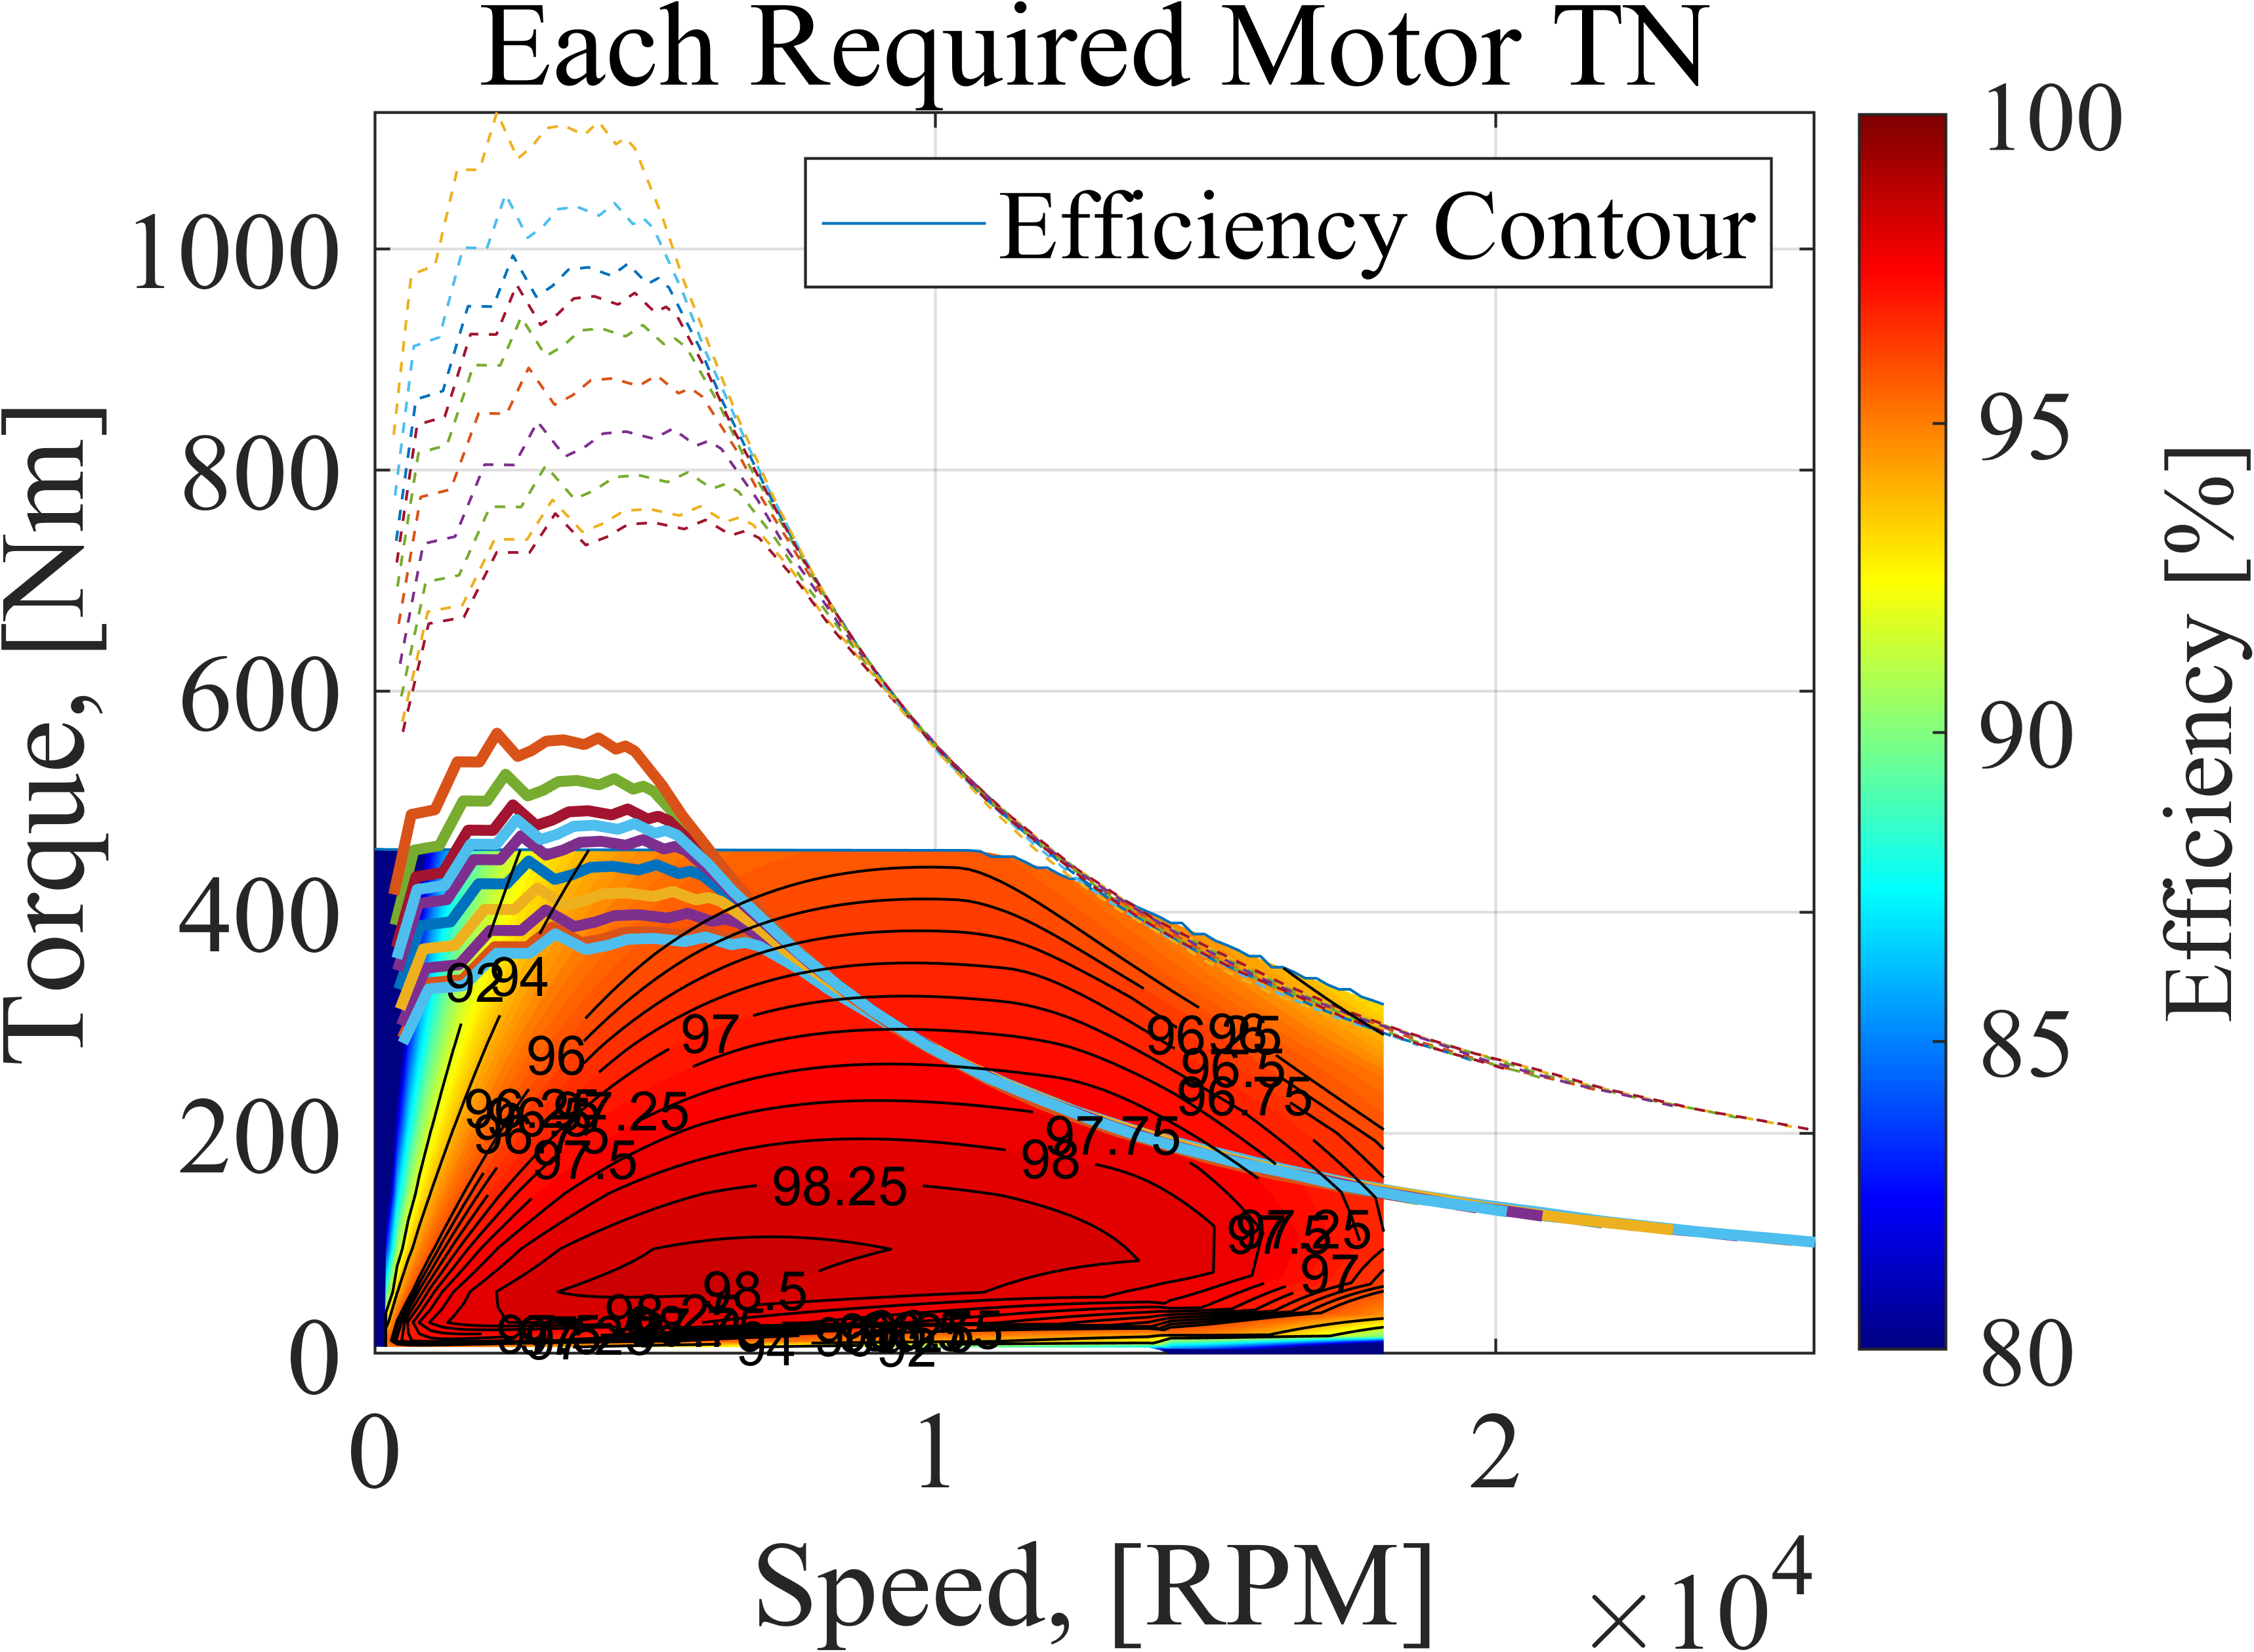

두 커브가 만나는점 (Base Point와 최대속도에서 만나는점)

모터의

#### [TB]최대전류에서 전류밀도

CurrentDensity
IpkLab
AreaCopper
BaseSpeed

#### [미정] Plot OP 포인트 - 전류 /위상각

% Define OP point First
OPInfo.Shaft_Torque
OPInfo.Speed
OPInfo.Shaft_Power
OPInfo.Ipk
OPInfo.PhaseAdvance

## 3) [KDH]OP 온도 상승해석

% User Defined Duty Cycle
% ref_Duty_Cycle=join(dirname(dirname(OSL_PROJECT_DIR)), 'DutyCycleData',ext_Duty_Cycle[0])+'.dat'
% mcad.LoadDutyCycle(ref_Duty_Cycle)


###  [draft]  Thermal>OP포인트 온도상승해석)

1) 차량 성능 기준 요구 곡선 OP포인트

rpm, torque, 제한온도 지정

2) 전류/전압 조건 기준 OP포인트 해석

            - 입력

                온도해석

                최종온도

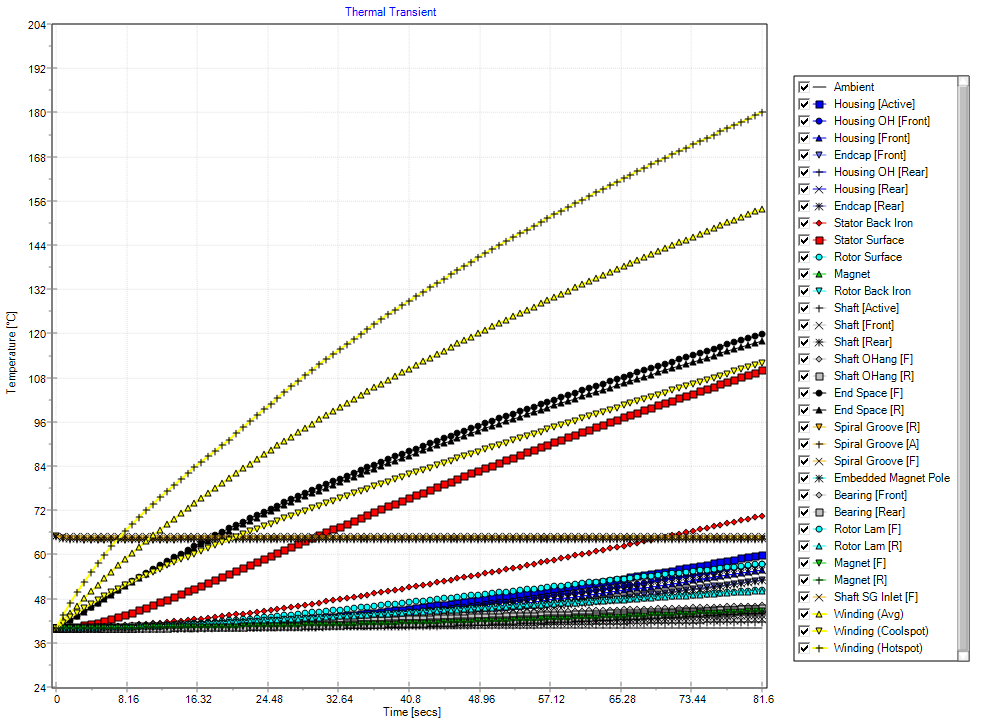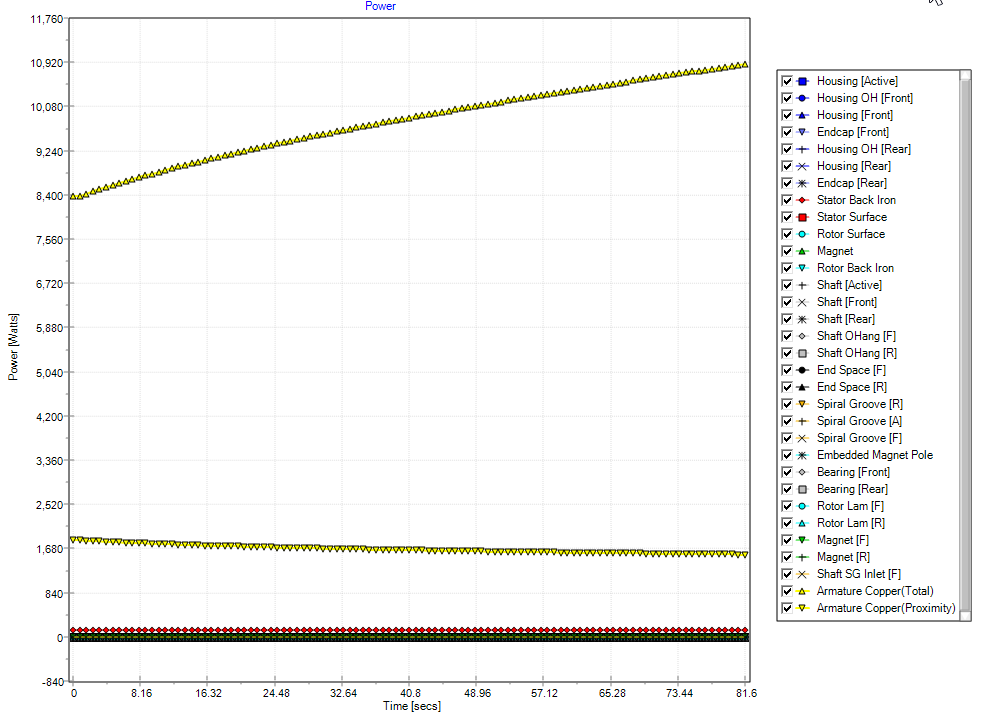

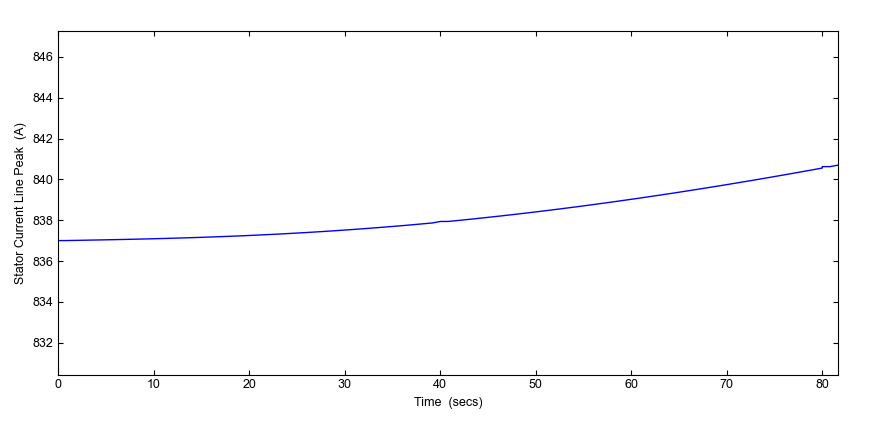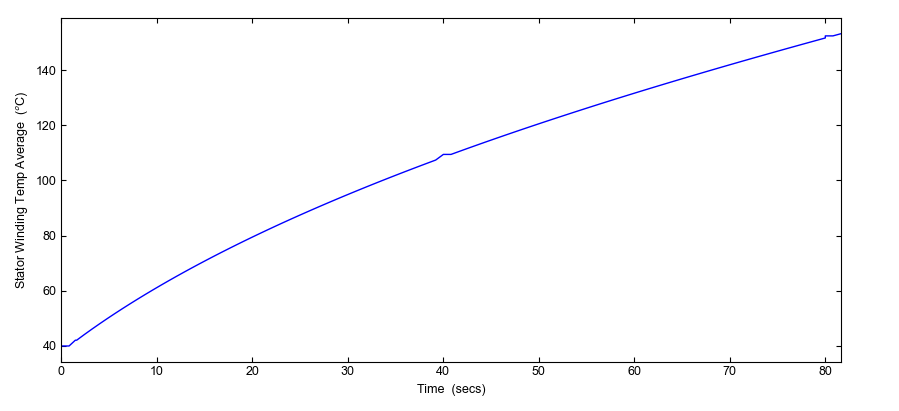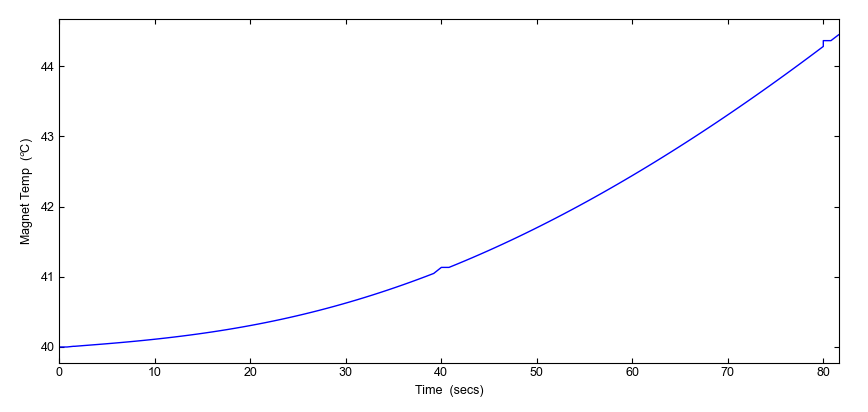

% 계산시간 체크 -517sec
mcad.DoTransientAnalysis()
% Closed Coupled
% 1) steady-state Iteration
% 2) Transient Progress
% 3) 결과 Time


mcad.SaveTransientTemperatures(TransientTempFileName)
mcad.SaveTransientPowerValues(TransientPowerfileName)

mcad=actxserver('motorcad.appautomation');
setGraphName = 'Wdg (Average) (C11)';
dataIndex = 0;
[ex,NumGraphPoints] = mcad.GetVariable('Last_Transient_Point')

List_xvalue = [];
List_valueforGraph = [];

for loop = 0:NumGraphPoints
    [success, x, y] = mcad.GetTemperatureGraphPoint(setGraphName, loop);
    if success == 0
        List_xvalue = [List_xvalue, x];
        List_valueforGraph = [List_valueforGraph, y];
    end
end

plot(List_xvalue,List_valueforGraph)



###  [Time Check] Lab>Therm>Transient (단시간 TN제한)

            제한온도 도달 시간

            제한시간 온도

                - 권선

                - 자석

% 계산시간 체크 


## 3. csv출력

#### 제약조건

% steady
 MaxWindTemp_MotorLAB

 % OP Point

 % DOE - MaxLimit, Max Voltage, 형상 
% OP 만족 하는 지 안하는지


#### 목적함수

o_Wh_Loss


#### 참조용 Output